x0=10*1000;
z0 = 700;
g=9.81;
v0=15.7*1000;


syms theta
eq = @(theta) z0.*cos(theta) - sin(theta).*cos(theta).*x0 + g.*x0.^2./2./v0.^2

eq = 包含以下值的 function_handle :
    @(theta)z0.*cos(theta)-sin(theta).*cos(theta).*x0+g.*x0.^2./2./v0.^2


theta_0 = deg2rad(10)

theta_0 = 0.1745

fplot(eq)
xlim([0,pi/2])
hold on 
f = @(theta) 0

f = 包含以下值的 function_handle :
    @(theta)0


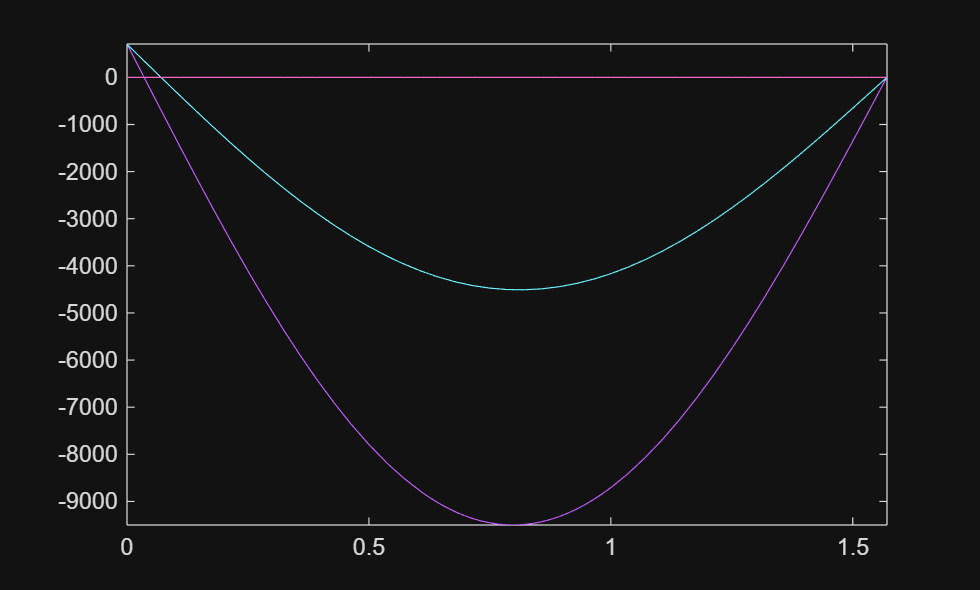

fplot(f)

tic
theta_sol_rad = fsolve(eq, theta_0)


方程已解。

fsolve 已完成，因为按照函数容差的值衡量，
函数值向量接近于零，并且按照梯度的值衡量，
问题似乎为正则问题。

<停止条件详细信息>


theta_sol_rad = 0.0354

toc

历时 0.008379 秒。


theta_sol = rad2deg(theta_sol_rad)

theta_sol = 2.0286

tic
alpha = asin((z0+g*x0^2/v0^2)/sqrt(z0^2+x0^2))

alpha = 0.0358

toc

历时 0.002368 秒。
